L'obiettivo di questo progetto è controllare e stabilizzare l'angolo di pitch di una moto quando la ruota anteriore è sollevata dal suolo.

Dalla letteratura il sistema non lineare nello spazio di stato, di ordine 2 $(n = 2)$, è il seguente:


$$\left \{ \begin{array}{rl} &\ddot{x} = \frac{F}{m}+\ddot{\phi}l\sin (\phi)\\
&\ddot{\phi} [ml^2 +J -ml^2\sin^2(\phi)] = Fl\sin(\phi)-mgl\cos(\phi)
\end{array}
\right.
$$


laddove $\phi > \phi_0 = 0
$ (il controllore entra in azione solamente quando la ruota anteriore è sollevata dal suolo) e la forza $F(t)
$ costituisce l'input del sistema.

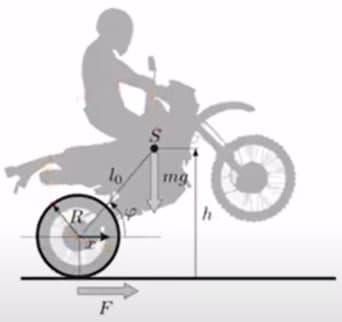


$$\left \{ \begin{array}{rl} &\phi_0 =0\\ &m= 230kg\\&l=1m\\&J = 2100kg*m^2\\&g=9.81\frac{m}{s^2}
\end{array}
\right.$$


Scelte le variabili di stato $x_1 =\phi, 
$ $x_2 = \dot{\phi}$ il modello non lineare è il seguente:


$$\dot{x} = f(x)+g(x)u = \left[\matrix{ x_2 \cr -\frac{mgl\cos(x_1)}{ml^2+J-ml^2\sin^2(x_1)}} \right] +   \left[\matrix{0 \cr \frac{l\sin(x_1)}{ml^2+J-ml^2\sin^2(x_1)}} \right]u\\
y = h(x) = x_1
$$


La tecnica utilizzata per la linearizzazione globale del sistema è la I/O Feedback Linearization.

Di conseguenza, si procede col calcolo delle derivate di Lie per identificare il grado relativo del sistema.


$$L_g (h(x)) = \frac{\partial h(x)}{\partial x}g(x)=  \left[\matrix{ 1 & 0}\right] \left[\matrix{  0 \cr \frac{l\sin(x_1)}{ml^2+J-ml^2\sin^2(x_1)}} \right]  = 0
$$


Con la prima derivata di Lie, si evince che il grado relativo $r$ è maggiore di $1
$. Come suggerito dai passi progettuali, è necessario differenziare nuovamente l'uscita calcolando $L_g(L_f (h(x))$.


$$L_f(h(x)) = \frac{\partial h(x)}{\partial x} f(x) = \left [\matrix {1 & 0} \right] \left[\matrix{ x_2 \cr -\frac{mgl\cos(x_1)}{ml^2+J-ml^2\sin^2(x_1)}} \right] = x_2$$


s

Essendo l'ordine del sistema uguale al grado relativo $(n=r=2)
$, non sono presenti dinamiche non osservabili. Da notare, che $x_1

$ sarà sempre diverso da 0 per ipotesi e, come avviene anche per l'abs, tale dispositivo di controllo si attiva solamente sotto certe condizioni (in tal caso qualora $\phi\neq0
$).

Una volta definito il grado relativo del sistema, l'ultimo passo progettuale prevede la definizione dell'ingresso di controllo "linearizzante" $u

$.


$$L_f^2(h(x)) = \frac{\partial L_f (h(x))}{\partial x} f(x) = \left [\matrix {0 & 1} \right] \left[\matrix{ x_2 \cr -\frac{mgl\cos(x_1)}{ml^2+J-ml^2\sin^2(x_1)}} \right] = - \frac{mgl\cos(x_1)}{ml^2+J-ml^2\sin^2(x_1)}$$



$$u = - \frac{L_f^2(h(x))}{L_g(L_f(h(x)))}+ \frac{1}{L_g(L_f(h(x)))}v = \frac{mglcos(x_1)}{l\sin(x_1)}+\frac{ml^2+J-ml^2sin^2(x_1)}{l\sin(x1)}v$$


Pertanto, sostituendo la $u$ calcolata nel sistema nella forma in spazio di stato, l'ingresso equivalente sarà uguale a $v = \ddot{y}
$. Da ciò ne consegue che il processo risultante dalla linearizzazione globale può essere visto come un doppio integratore. 

clear all;
close all;
syms s



$$\dot{x} = Ax+ Bu = \left [\matrix {0& 1 \cr 0 & 0}\right]x +\left[\matrix{0 \cr 1}\right]u\\\\
y = Cx = \left[\matrix{1 & 0}\right]x
$$


A = [0 1; 0 0];
B = [0; 1];
C = [1 0];
D = 0;

Aggiungendo l'azione integrale il sistema diventa:


$$\dot{x} = Ax+ Bu = \left [\matrix {0& 1 \cr 0 & 0}\right]x +\left[\matrix{0 \cr 1}\right]u\\
\dot{z} = y - r = Cx -r \\$$


Scritto in forma matriciale diventa:


$$\left[\matrix {\dot{x} \cr \dot{z}}\right] = \left[\matrix{A & 0 \cr C & 0}\right]\left[\matrix {x \cr z}\right]+\left[\matrix {B \cr 0}\right]u + \left[\matrix {0\cr -1}\right]r$$


Sostituendo l'ingresso di controllo $u = -kx-k_i z$, si ottiene:


$$\left[\matrix {\dot{x} \cr \dot{z}}\right] = \left[\matrix{A-Bk & -Bk_i  \cr C & 0}\right]\left[\matrix {x \cr z}\right]+\left[\matrix {Bk_r \cr -1}\right]r$$


As = [A [0;0] ; C 0]

As =      0     1     0
     0     0     0
     1     0     0


Bs = [B; 0]

Bs =      0
     1
     0


Cs = [C 0]

Cs =      1     0     0


Ds = 0

Ds = 0

Verifica della raggiungibilità:

%% Raggiungibilità 
Wr = [B A*B]

Wr =      0     1
     1     0


det(Wr) % Il sistema è raggiungible

ans = -1

Verifica osservabilità:

%% Osservabilità
Wo = [C; C*A]

Wo =      1     0
     0     1


det(Wo) % Il sistema è osservabile 

ans = 1

LQR per la raggiungibilità:

%%Pole placement
[NumRowsAs NumColsAs]=size(As);
[NumRowsBs NumColsBs]=size(Bs);
Qx = [1 0 0; 0 1 0; 0 0 1]

Qx =      1     0     0
     0     1     0
     0     0     1


Qu = 1

Qu = 1

[k, S, P] = lqr(As, Bs, Qx, Qu)

k =     2.4142    2.4142    1.0000


S =     4.8284    2.4142    2.4142
    2.4142    2.4142    1.0000
    2.4142    1.0000    2.4142


P =   -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -1.0000 + 0.0000i


Osservabilità:


$$\hat{\dot{x}} = A\hat{x}+Bu+L(y-C\hat{x}) $$


[NumRowsB NumColsB]=size(B);
Qx = [100 0; 0 100];  
Qu = eye(NumColsB);
[L_t, S, P] = lqr(A.', C.', Qx, Qu); 
L=L_t.'

L =    10.9545
   10.0000


Definizione filtro di Kalman:

[L_tK, S, P] = lqe(A ,[100 0; 0 100], C, Qx, Qu)

L_tK = 	1.0e+03 *

    1.0010
    1.0000


S = 	1.0e+06 *

    0.0010    0.0010
    0.0010    1.0010


P =    -1.0000
 -999.9995


%% Run simulation on Simulink
open_system('motorcycle_LQR_with_integral_action.slx') 
